clear; clc; close all

Load a test image

impath = ".\data\spiral\training\parkinson"

impath = ".\data\spiral\training\parkinson"

imname = "\V03PE05.png"

imname = "\V03PE05.png"

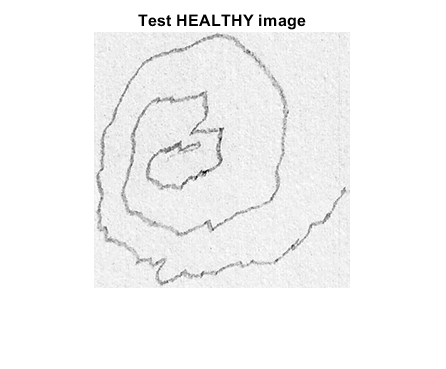

im = im2double(rgb2gray(imread(impath + imname)));
imshow(im, []); title('Test HEALTHY image')

[M,N] = size(im);

View image histogram

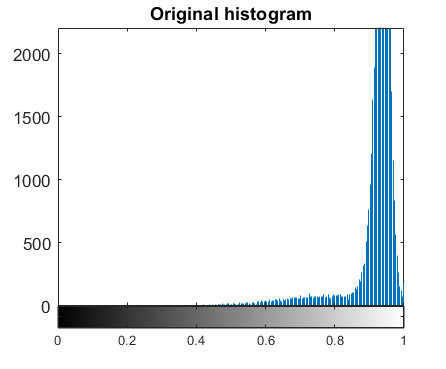

imhist(im);
title('Original histogram');

Apply Otsu's method thresholding to get the ROI of the stroke. Isolate the stroke.

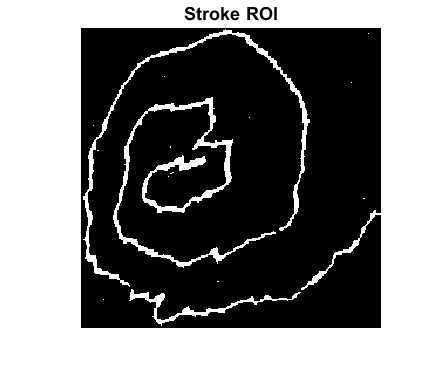

T = graythresh(im);
ROI = im < T;
ROI = imclose(ROI, strel("square", 4));
imshow(ROI); title('Stroke ROI')

Get the skeleton of the image and prune it

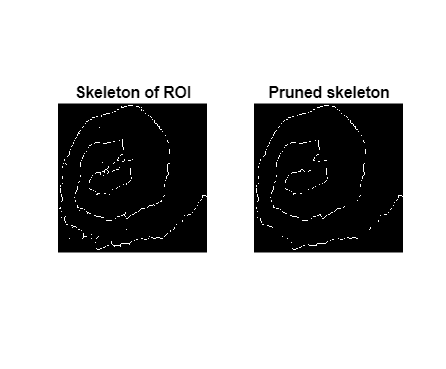

skel_im = bwmorph(ROI, 'skel', Inf);
subplot(121);imshow(skel_im); title('Skeleton of ROI')
pruned_skel_im = bwmorph(skel_im, 'spur', 10);

% Remove single, isolated pixels from the image
pattern = zeros(3); pattern(2,2) = 1;
single_pixels = myhitnmiss(pruned_skel_im, pattern, 1); [spy, spx] = find(single_pixels);
pruned_skel_im(spy, spx) = 0;

subplot(122);imshow(pruned_skel_im); title('Pruned skeleton')

Prepare for the region growing procedure:

Get a starting position

% First we need to get one of the starting points. Hit or miss. No matter
% which one we take and the order of growing, because we will look at the
% spectral information of the signal.

% Find endpoints and get the outermost one (no particular reason, just to be
% consistent)
hits = bwmorph(pruned_skel_im, 'endpoints'); [endpy, endpx] = find(hits);

% Measure euclidean distance to center and take biggest (furthest point
% from center)
[M, N] = size(im);
C = round(0.5*[M, N]);
dists = sqrt((endpy-C(1)).^2 + (endpx-C(2)).^2); [~, biggest] = max(dists);
Y_init = endpy(biggest); X_init = endpx(biggest);


Start region growing.

% target_im = zeros(M,N); target_im(Y_init, X_init) = 1;
% dilater = strel('square', 3);
% 
% Xk = target_im;
% i = 1;
% canv_n = pruned_skel_im;
% figure;
% while (1)
%     canv = canv_n;
%     canv = xor(canv, Xk);
%     dil_point = imdilate(Xk, dilater);
%     new_point = canv & dil_point;
%     canv_n = xor(canv, new_point);
%      % pause(0.001)
%     if  isequal(canv, canv_n) || isequal(canv_n, zeros(M,N))%(i ~= 0 && Y_pts(i) == Y_pts(i-1) && X_pts(i) == X_pts(i-1))
%         break;
%     else
%     Xk = new_point;
%         [Y_pts(i), X_pts(i)] = find(new_point, 1); 
%     end
%     i = i + 1;
% %     if i>26
%         subplot(221);imshow(canv); axis on
%         subplot(222);imshow(dil_point); axis on
%         subplot(223);imshow(canv_n); axis on
%         subplot(224);plot(X_pts);title('X')
%         disp(num2str(X_pts(end)));
%         pause;
% %     end
% end
% 
% for cK = 1:length(X_pts)
%     sig(cK) = im(Y_pts(cK), X_pts(cK));
% end

Another approach...

target_im = zeros(M,N); target_im(Y_init, X_init) = 1;
dilater = strel('square', 3);

Xk = target_im;
i = 1;

canv_n = pruned_skel_im;
canv_n = padarray(canv_n, [1,1], 0);
[M, N] = size(im);
pointy = Y_init + 1; pointx = X_init + 1; % Add 1 because we padded !!!
p = 0;

while ~isequal(canv_n, zeros(size(canv_n)))
    while (1)
        canv_n(pointy, pointx) = 0;
        p = find(canv_n(pointy-1:pointy+1, pointx-1:pointx+1));
        if isempty(p)
            break;
        end
        p = p(1);

        switch p
            case 1
                pointy = pointy - 1;
                pointx = pointx - 1;
            case 2
                pointx = pointx - 1;
            case 3
                pointy = pointy + 1;
                pointx = pointx - 1;
            case 4
                pointy = pointy - 1;
            case 6
                pointy = pointy + 1;
            case 7
                pointy = pointy - 1;
                pointx = pointx + 1;
            case 8
                pointx = pointx + 1;
            case 9
                pointy = pointy + 1;
                pointx = pointx + 1;
        end
        X_pts(i) = pointx;
        Y_pts(i) = pointy;

        i = i + 1;
    end
    hits = bwmorph(pruned_skel_im, 'endpoints');
    hits(:,end) = 0; hits(:,1) = 0; hits(1,:) = 0; hits(end,:)= 0; % Prevent border effect hits
    [endpy, endpx] = find(hits);
    % Measure euclidean distance to center and take biggest (furthest point from center)
    C = round(0.5*[M, N]);
    dists = sqrt((endpy-C(1)).^2 + (endpx-C(2)).^2); [~, biggest] = max(dists);
    pointy = endpy(biggest); pointx = endpx(biggest);
end
subplot(132);plot(X_pts);title('X')
subplot(133);plot(Y_pts);title('Y')